# Score Fusion For Screen Contents

To fuse the scores, two images, $\mathrm{ref}$, and $\mathrm{dst}$, are fed to FR algorithms. Each algorithm generates a score. These scores comprise a feature vector. A SVR then maps this feature vector to a final quality measure.

The SQMS [1] was used as a base SCI-FR algorithm and the effect of combining it with the following FR algorithms was studied.

- HaarPSI [2]

- VIF [2]

- GMSD [3]

- LBPSI [4]

Since Wavelet's horizontal and vertical subbands are found to be effective in representing text structures, HaarPSI was included. The same justification applies to using LBPSI [4], which is a FR QA algorithm for document images. Contrast change is a challenging distortion for assessors and the information theory-based method, VIF, seems to be the best for such distortions. GMSD is also incorporated to consider gradient degradations.

The following cobminations were possible, and were considered for experiments:

1- "SQMS"

2- "SQMS+HaarPSI"

3- "SQMS+GMSD"

4- "SQMS+VIF"

5- "SQMS+LBPSI"

6- "SQMS+HaarPSI+GMSD"

7- "SQMS+HaarPSI+VIF"

8- "SQMS+HaarPSI+LBPSI"

9- "SQMS+GMSD+VIF"

10- "SQMS+GMSD+LBPSI"

11- "SQMS+VIF+LBPSI"

12- "SQMS+HaarPSI+GMSD+VIF"

13- "SQMS+HaarPSI+GMSD+LBPSI"

14- "SQMS+HaarPSI+VIF+LBPSI"

15- "SQMS+GMSD+VIF+LBPSI"

( by *2- "SQMS+HaarPSI"* , we mean that the feature vector is the scores generated by SQMS and HaarPSI , $\vec{f} = [SQMS, HaarPSI ]$. The same is true for other 14 functions.  *1- SQMS* , is not a combination; it is the single score generated by SQMS. )

## Datasets

SCID has 9 distortions, and SIQAD has 7. The table summarizes the information of the datasets.


$$\matrix{
\text{Dataset}&\text{\#Refs}&\text{#Dsts}&\text{\#Dst Levels}&\text{Dst types}\cr
SIQAD[6]&20&980&7&GN-GB-MB-CC-JPEG-JPEG2000-LSC\cr
SCID [7]&40&1800&5&GN-GB-MB-CC-JPEG-JPEG2000-CSC-HEVC-CQD
}$$


We see that six distortions are common. ( A description of distortions is provided at the end of the document. )

## Testing the Entire Datasets

In the first experiment, the methods were evaluated on the entire datasets. 

**Train & Test**

//

for 1000 times:

            80% of the scenes in the dataset were randomly selected for training and the rest 20% for test.

            The SROCC was computed for the current train-test.

The median SROCC is reported.

//

**Cost & Gamma**

//

for Cost in:$\{2^{-3}, 2^{-1}, 2^{+1}, 2^{+3}, 2^{+5}, ..., 2^{+15}\}$

        for Gamma in:$\{2^{-15}, 2^{-13}, 2^{-11},..., 2^{-1}, 2^{+1}, 2^{+3}\}$

                for 100 times:

                        80% of the scenes **in the entire dataset **were randomly selected for training and 20% for test.

                        The SROCC was saved for current train-test suffle.

                The median SROCC was saved for the current Cost and Gamma

The (Cost, Gamma) pair with the best median SROCC was selected.

//

The following shows the results for SQMS and its combination with other metric.

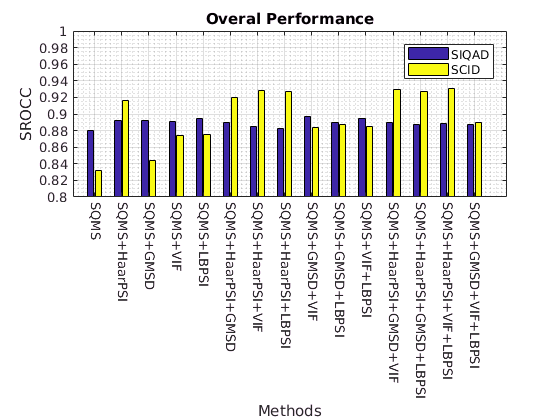

% this is just the code for plotting the data.
load('data_SCID.mat');
load('data_SIQAD.mat');
load('f_names_15.mat');
for ii = 1:15
    all_two_datasets(1,ii) = data_SIQAD{end, ii+1};
    all_two_datasets(2, ii) = data_SCID{end, ii+1};
end
bar(all_two_datasets'), legend('SIQAD', 'SCID'),grid('on'), grid('minor'),...
    xticks(1:15), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0.8:0.02:1), xlim([0.2 16.2]),ylim([0.8 1]), ...
    ylabel('SROCC'), xlabel('Methods'),title('Overal Performance')

It is seen that the accuracy is sufficiently improved for SCID, while the performance gain is minor for SIQAD. To better visualize, we plot the following:

$|SROCC_{F_i}|-|SROCC_{SQMS}|$ for $i\in\{1,\ldots, 14\}$

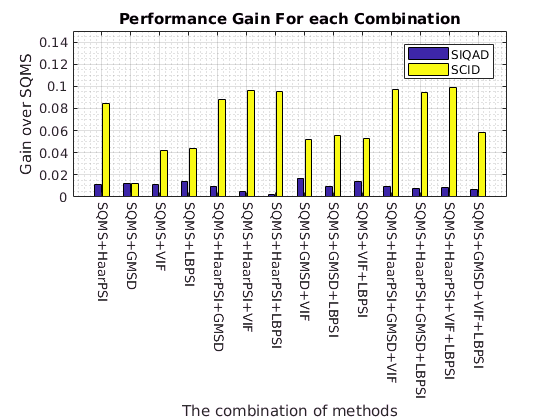

% visualization
gain(1,1:14) = abs(all_two_datasets(1,2:15))-abs(all_two_datasets(1,1));
gain(2,1:14) = abs(all_two_datasets(2,2:15))-abs(all_two_datasets(2,1));
bar(gain'), legend('SIQAD', 'SCID'),grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    yticks(0:0.02:0.15), ylim([0 0.15]), ...
    ylabel('Gain over SQMS'), xlabel('The combination of methods'), title('Performance Gain For each Combination')

It is seen that the bare combination with HaarPSI (first column), performs better than combining SQMS with all the other methods (last column). (*Any explanations?) *However, the most gain for SIQAD was achieved by SQMS+GMSD+VIF.

## Individual Distortions

To test the performance on a specific distortion, a 80-20 split on the entire dataset is perfromed. The model is trained on the entire 80%. In the test stage, only those images in the 20% are used which have that specific distortion. This is the paradigm suggested in [8].The Cost and Gamma here, are the ones optimized for the entire dataset in the previous experiment. Formally:

//

for each distortion

            for 1000 times:

                        80% of the scenes in the dataset were randomly selected for training.

                        In the remaining 20%, only those with the current distortion are used for testing

                        The SROCC was computed for the current train-test.

            The median SROCC is saved for the current distortion.

//

**Cost & Gamma**

(This is the same as previous stage)

//

for Cost in:$\{2^{-3}, 2^{-1}, 2^{+1}, 2^{+3}, 2^{+5}, ..., 2^{+15}\}$

        for Gamma in:$\{2^{-15}, 2^{-13}, 2^{-11},..., 2^{-1}, 2^{+1}, 2^{+3}\}$

                for 100 times:

                        80% of the scenes **in the entire dataset **were randomly selected for training and 20% for test.

                        The SROCC was saved for current train-test suffle.

                The median SROCC was saved for the current Cost and Gamma

The (Cost, Gamma) pair with the best median SROCC was selected.

//

The following shows the distortion-specific results for all 15 metrics on SIQAD:

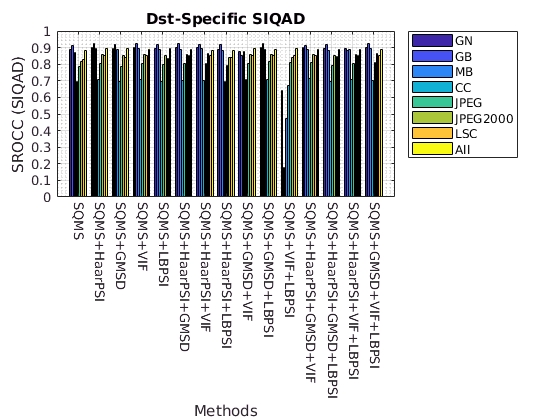

% visualization
load('tabular_whole_SIQAD.mat');
bar(abs(tabular_whole_SIQAD)'), ...
    legend(data_SIQAD(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1), ylim([0 1])
    ylabel('SROCC (SIQAD)'), xlabel('Methods'), title('Dst-Specific SIQAD')

More interesting information are attained if we plot the gain with respect to SQMS:

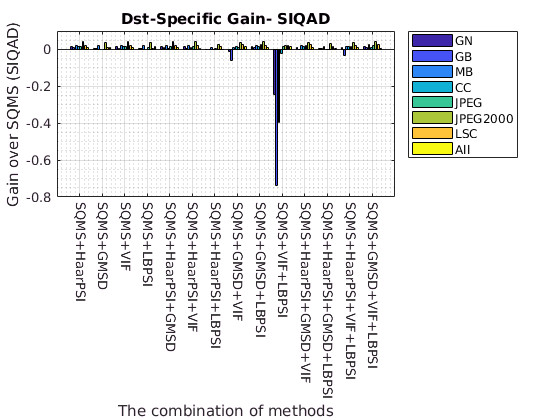

gain_dst_SIQAD(:,1:14) = abs(tabular_whole_SIQAD(:, 2:15))-abs(tabular_whole_SIQAD(:,1));
bar(gain_dst_SIQAD'),...
    legend(data_SIQAD(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SIQAD)'), xlabel('The combination of methods'), title('Dst-Specific Gain- SIQAD')

the same charts are plotted for SCID:

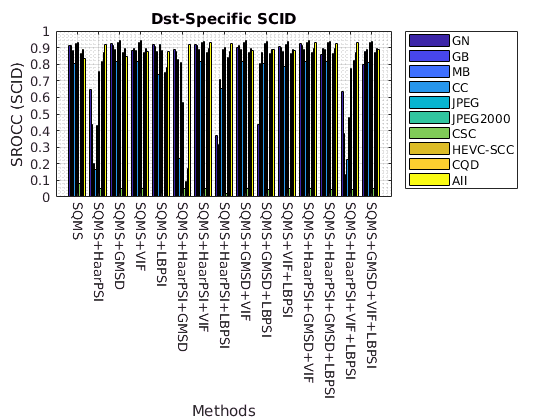

% visualization
load('tabular_whole_SCID.mat');
bar(abs(tabular_whole_SCID)'), ...
    legend(data_SCID(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1), ylim([0 1])
    ylabel('SROCC (SCID)'), xlabel('Methods'), title('Dst-Specific SCID');

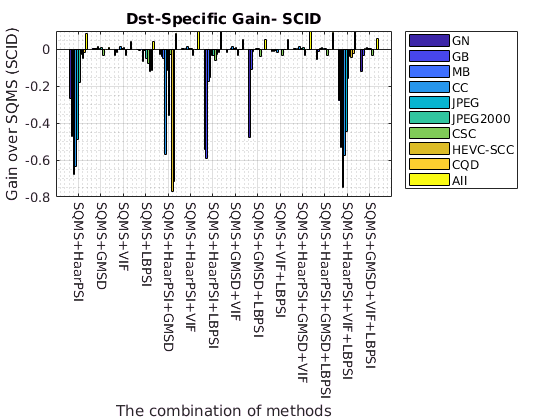

gain_dst_SCID(:,1:14) = abs(tabular_whole_SCID(:, 2:15))-abs(tabular_whole_SCID(:,1));
bar(gain_dst_SCID'),...
    legend(data_SCID(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SCID)'), xlabel('The combination of methods'), title('Dst-Specific Gain- SCID')

A noticable irony is that, altough the presence of HaarPSI is very effective for improving the model accuracy on the entire SCID, the model is inferior to SQMS for all distortions (The 1st column). 

How can a feature vector improve the performance on the entire dataset, but have such poor performance on indvidual distortions?

It must be noted that the model which was trained and tested on individual distortions, used the same $(C,\gamma)$optimized for the entire dataset. Although optimizing the parameters for train-test sets of each distortion is not fair, but it was tested whether it increases the per-distortion accuracy.

The optimization procedure was as follows:

//

for each distortion

            for Cost in:$\{2^{-3}, 2^{-1}, 2^{+1}, 2^{+3}, 2^{+5}, ..., 2^{+15}\}$

                    for Gamma in:$\{2^{-15}, 2^{-13}, 2^{-11},..., 2^{-1}, 2^{+1}, 2^{+3}\}$

                            for 100 times:

                                    80% of the scenes **in the entire dataset **were randomly selected for training 

                                    In the remaining 20%, those images with the current distortion were used for test.

                                    The SROCC was saved for current train-test suffle.

                            The median SROCC was saved for the current Cost and Gamma

            The (Cost, Gamma) pair with the best median SROCC was selected for current distortion

//

The following shows the results after per-distortion parameter optimization.

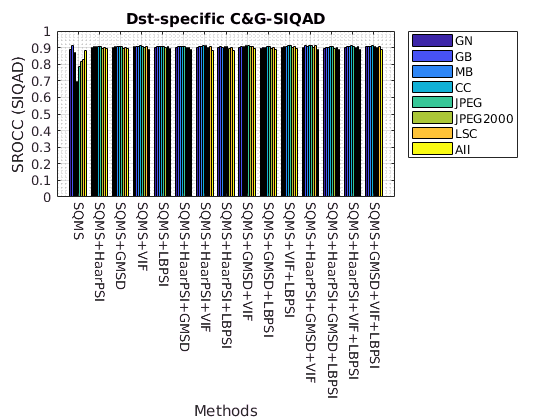

% visualization
load('tabular_whole_SIQAD_cg.mat');
bar(abs(tabular_whole_SIQAD_cg)'), ...
    legend(data_SIQAD(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1), ylim([0 1])
    ylabel('SROCC (SIQAD)'), xlabel('Methods'), title('Dst-specific C&G-SIQAD');

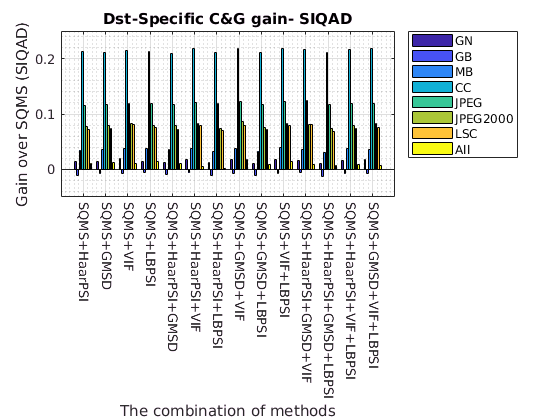

    gain_dst_SIQAD_cg(:,1:14) = abs(tabular_whole_SIQAD_cg(:, 2:15))-abs(tabular_whole_SIQAD_cg(:,1));
bar(gain_dst_SIQAD_cg'),...
    legend(data_SIQAD(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SIQAD)'), xlabel('The combination of methods'), title('Dst-Specific C&G gain- SIQAD');

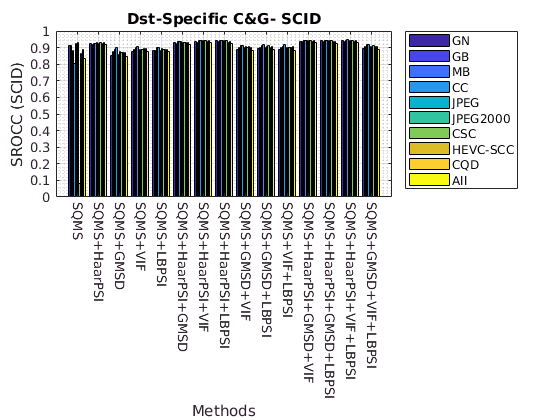

% visualization
load('tabular_whole_SCID_cg.mat');
bar(abs(tabular_whole_SCID_cg)'), ...
    legend(data_SCID(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1), ylim([0 1])
    ylabel('SROCC (SCID)'), xlabel('Methods'), title('Dst-Specific C&G- SCID')

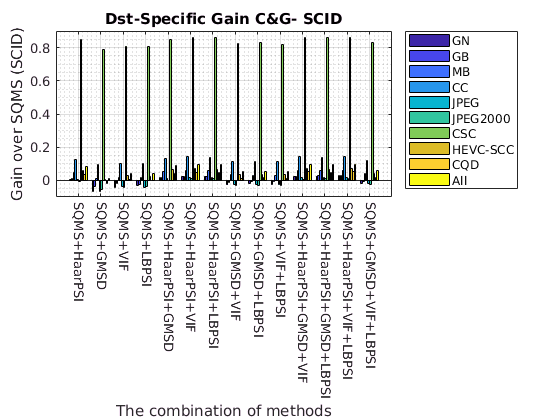

    gain_dst_SCID_cg(:,1:14) = abs(tabular_whole_SCID_cg(:, 2:15))-abs(tabular_whole_SCID_cg(:,1));
bar(gain_dst_SCID_cg'),...
    legend(data_SCID(2:end, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SCID)'), xlabel('The combination of methods'), title('Dst-Specific Gain C&G- SCID');

Even after dst-specifc $C\&\gamma$ optimization, the performance of many fused methods are lower than SQMS for some distortions in SCID. 

All fused method had a lower performance on `Guassian Blur' in SIQAD in comparison to SQMS (*any reasoning?)*

## Cross Dataset Evaluation

6 distortions, namely, *Guassian Noise, Gaussian Blur, Motion Blur, Contrast Change, Jpeg, *and* Jp2K*, were common in the two datasets.

A model was trained on the 6 distortions of a dataset and tested on the same distortions of the other dataset. $C\&\gamma$ were the optimized parameters in the first experiment (for the entire dataset).

The following shows the results for 14 combinations and SQMS.

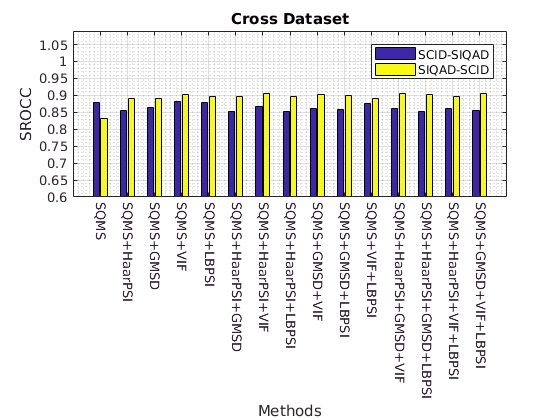

load('./cross_dataset/cross_p_SCID_SIQAD.mat');
load('./cross_dataset/cross_p_SIQAD_SCID.mat');
all_cross(1,1) = all_two_datasets(1,1);
all_cross(1,2:15) = spear_results_dq(1,:);
all_cross(2,1) = all_two_datasets(2,1);
all_cross(2,2:15) = spear_results_qc(1,:);
bar(abs(all_cross)'), legend('SCID-SIQAD', 'SIQAD-SCID'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xticklabels(f_names_15), xtickangle(-90),xlim([0 16]),...
    ylabel('SROCC'), xlabel('Methods'),title('Cross Dataset'), ylim([0.6 1.09]), yticks(0.6:0.05:1.09)

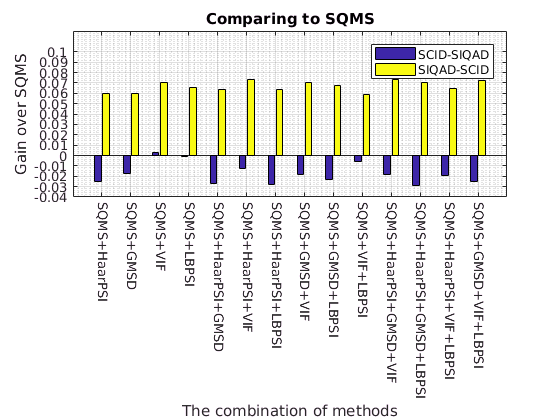

gain_cross(1,1:14) = abs(all_cross(1,2:15))-abs(all_cross(1,1));
gain_cross(2,1:14) = abs(all_cross(2,2:15))-abs(all_cross(2,1));
bar(gain_cross'), legend('SCID-SIQAD', 'SIQAD-SCID'),grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    yticks(-0.04:0.01:0.1), ylim([-0.04 0.12]), ...
    ylabel('Gain over SQMS'), xlabel('The combination of methods'), title('Comparing to SQMS')

Although SQMS+VIF did not have a spectecular performance in previous experiments, it is the only one with a positive gain on both cross-dataset evaluations.

Performance on individual 6 common distortions was evaluated with the following setting.

training: on the distortion $\#i$of the train dataset.

testing: on the distortion $\#i$of the test dataset.

$C\&\gamma$: the same as the entire dataset's.

Results for SCID-SIQAD:

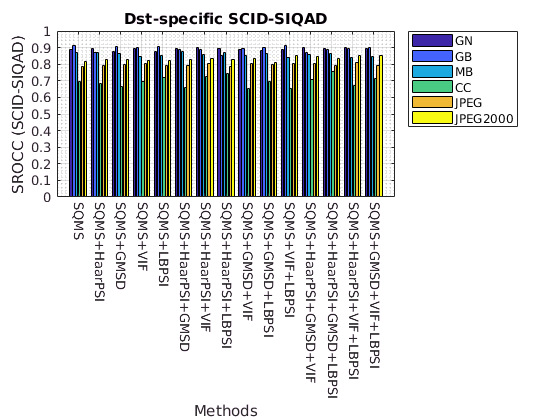

load('./cross_dataset/cross_p_dst_SCID_SIQAD.mat');
dst_SCID_SIQAD(:,1) = tabular_whole_SIQAD(1:6,1);
dst_SCID_SIQAD(:, 2:15) = reshape(spear_results_dq_dst(1,:,:), [6, 14]);
bar(abs(dst_SCID_SIQAD)'), ...
    legend(data_SIQAD(2:7, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1),ylabel('SROCC (SCID-SIQAD)'), xlabel('Methods'), ...
    title('Dst-specific SCID-SIQAD');

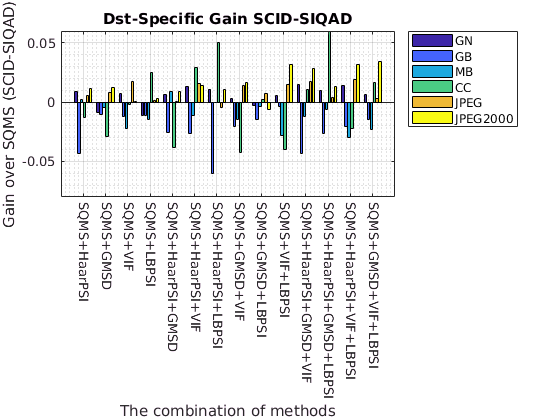

gain_dst_SCID_SIQAD(:,1:14) = abs(dst_SCID_SIQAD(:, 2:15))-abs(dst_SCID_SIQAD(:,1));
bar(gain_dst_SCID_SIQAD'),...
    legend(data_SCID(2:7, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SCID-SIQAD)'), xlabel('The combination of methods'), title('Dst-Specific Gain SCID-SIQAD');

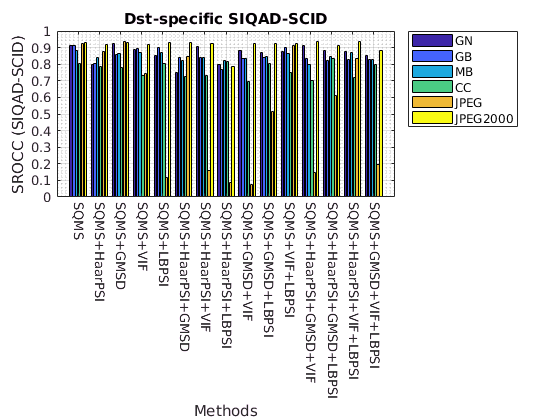

load('./cross_dataset/cross_p_dst_SIQAD_SCID.mat');
dst_SIQAD_SCID(:,1) = tabular_whole_SCID(1:6,1);
dst_SIQAD_SCID(:, 2:15) = reshape(spear_results_qc_dst(1,:,:), [6, 14]);
bar(abs(dst_SIQAD_SCID)'), ...
    legend(data_SIQAD(2:7, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:15), xlim([0 16]), xticklabels(f_names_15), xtickangle(-90),...
    yticks(0:0.1:1),ylabel('SROCC (SIQAD-SCID)'), xlabel('Methods'), ...
    title('Dst-specific SIQAD-SCID');

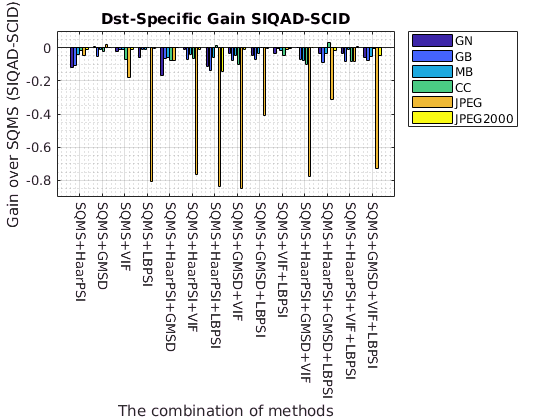

gain_dst_SIQAD_SCID(:,1:14) = abs(dst_SIQAD_SCID(:, 2:15))-abs(dst_SIQAD_SCID(:,1));
bar(gain_dst_SIQAD_SCID'),...
    legend(data_SCID(2:7, 1), 'location', 'northeastoutside'),...
    grid('on'), grid('minor'),...
    xticks(1:14), xticklabels(f_names_15(2:15)), xtickangle(-90),...
    ylabel('Gain over SQMS (SIQAD-SCID)'), xlabel('The combination of methods'), title('Dst-Specific Gain SIQAD-SCID');

The last figure demonstrates another irony. All combinations surpassed SQMS on the entire SIQAD-SCID, but most of them are less accurate for each distortion.

## Conclusion

What is reported as the performance of a SVR model is affected by train set, test set, and the parameters. If these factors are not controled, non of the above combinations are superior the single SQMS metric.

## References

[1] Gu, K., Wang, S., Yang, H., Lin, W., Zhai, G., Yang, X., & Zhang, W. (2016). Saliency-Guided Quality Assessment of Screen Content Images. *IEEE Transactions on Multimedia*, *18*(6), 1098–1110. [https://doi.org/10.1109/TMM.2016.2547343](https://doi.org/10.1109/TMM.2016.2547343)

[2] Reisenhofer, R., Bosse, S., Kutyniok, G., & Wiegand, T. (2018). A Haar wavelet-based perceptual similarity index for image quality assessment. *Signal Processing: Image Communication*. [https://doi.org/10.1016/j.image.2017.11.001](https://doi.org/10.1016/j.image.2017.11.001)

[3] Sheikh, H. R. H. R., & Bovik, A. C. A. C. (2006). Image information and visual quality. *IEEE Transactions on Image Processing*, *15*(2), 430–444. [https://doi.org/10.1109/TIP.2005.859378](https://doi.org/10.1109/TIP.2005.859378)

[4] Xue, W., Zhang, L., Mou, X., & Bovik, A. C. (2014). Gradient magnitude similarity deviation: A highly efficient perceptual image quality index. *IEEE Transactions on Image Processing*, *23*(2), 668–695. [https://doi.org/10.1109/TIP.2013.2293423](https://doi.org/10.1109/TIP.2013.2293423)

[5] Souza, A., Cheriet, M., Naoi, S., Suen, C. Y., de Souza, A. B., Wang, Q., … Doermann, D. (2016). Document image quality assessment based on texture similarity index. *Document Analysis Systems (DAS), 2016 12th IAPR Workshop On*, *1*(4), 132–137. [https://doi.org/10.1109/ICIP.2014.7025520](https://doi.org/10.1109/ICIP.2014.7025520)

[6] Yang, H., Fang, Y., & Lin, W. (2015). Perceptual Quality Assessment of Screen Content Images. *IEEE Transactions on Image Processing*, *24*(11), 4408–4421. [https://doi.org/10.1109/TIP.2015.2465145](https://doi.org/10.1109/TIP.2015.2465145)

[7] Ni, Z., Ma, L., Zeng, H., Chen, J., Cai, C., & Ma, K. K. (2017). ESIM: Edge Similarity for Screen Content Image Quality Assessment. *IEEE Transactions on Image Processing*, *26*(10), 4818–4831. [https://doi.org/10.1109/TIP.2017.2718185](https://doi.org/10.1109/TIP.2017.2718185)

[8] Li, Q., Lin, W., & Fang, Y. (2017). BSD: Blind image quality assessment based on structural degradation. *Neurocomputing*, *236*, 93–103. https://doi.org/10.1016/J.NEUCOM.2016.09.105

## Distortions in SCID

Generation of distorted SCIs in the SCID

The distorted SCIs are generated by applying various image operations to each reference SCI, individually. Image operations to generate 9 distortion types with 5 degradation levels (ranging from imperceptible level to highly-annoying one) are introduced as below:

- Gaussian Noise (GN): the corresponding distorted SCIs with GN are obtained by performing MATLAB function “*imnoise*”. The mean is zero, and the standard deviation is set as 0.001, 0.005, 0.01, 0.05 and 0.1, respectively.

- Gaussian Blur (GB): the corresponding distorted SCIs with GB are obtained by performing MATLAB function “*imfilter*” with Gaussian kernel. The size of the Gaussian kernel is 5×5, and the standard deviation is set to 0.58, 0.76, 0.96, 1.2 and 2.1, respectively.

- Motion Blur (MB): the corresponding distorted SCIs with MB are obtained by performing MATLAB function “*imfilter*” with motion kernel, which stimulates the linear motion of a camera. The blurring level is controlled by the following two parameters “len” and “theta”. The former one controls the linear motion of a camera by ‘len’ pixels, while the latter one controls the degree of angle in a counterclockwise direction. In our experiments, ‘theta’ is zero and ‘len’ is set as 2, 3.4, 4, 5.5, and 6.4, respectively. 	

- Contrast Change (CC): the corresponding distorted SCIs with CC are obtained by performing MATLAB function “*imadjust*”. The contrast change level is controlled by the parameter “[low_in; high_in]” and “[low_out; high_out]”, which individually means the scale of the reference SCI and contrasted changed SCI. In our experiments, ([low_in; high_in], [low_out; high_out]) is set as: ([ ; ], [0.3; 0.5]), ([ ; ], [0.1;0.7]), ([0.1;0.8],[0.1; 0.9]), ([0.2; 0.8],[0.1; 0.8]), and ([0.2; 0.7],[ ; ]), respectively.

- JPEG compression: the corresponding distorted SCIs with JPEG compression are obtained by performing MATLAB function “*imwrite*”. The quality factor is set as 75, 35, 18, 8, and 5, respectively.

- JPEG2000 compression: the corresponding distorted SCIs with JPEG2000 compression are obtained by performing JasPer software [a], [b] (in this response letter). The compression ratio is set as 0.08, 0.045, 0.02, 0.015, and 0.01. 	JPEG 2000. [Online]. Available:	[https://jpeg.org/jpeg2000/software.html](https://jpeg.org/jpeg2000/software.html)	JasPer Software. [Online]. Available:	[http://www.ece.uvic.ca/~frodo/jasper/](http://www.ece.uvic.ca/~frodo/jasper/)

- Color Saturation Change (CSC): the corresponding distorted SCIs with CSC are obtained by keeping the luminance component unchanged while changing the chrominance components. Firstly, MATLAB function ‘rgb2ycbcr’ is used to transform SCI from RGB to YCbCr. Then, the chrominance component is adjusted according to the following equation`：`where ,, ,, , and  means the Y, Cb, Cr components of reference SCI and distorted SCI , respectively. is the parameter to control the level of color saturation change and is set as 0.96, 0.72, 0.58, 0.42, 0.1, respectively.

- HEVC Screen Content Compression (HEVC-SCC): the corresponding distorted SCIs with HEVC-SCC compression are obtained by performing HEVC-SCC encoder with standard configuration—“All Intra Main setting”. The quantization parameters are set as 16, 36, 40, 42, and 48, respectively. 		

- Color quantization with dithering (CQD): the corresponding distorted SCIs with CQD are obtained by performing MATLAB function “*rgb2ind*”. This function is used to convert RGB image to indexed image using dithering minimum variance quantization, where the parameter “N” is to control the number of color and is set as 30, 28, 25, 10, and 5, respectively. 	

## Distortions in SIQAD

Generation of distorted SCIs in the SIQAD

Seven distortion types with seven distortion levels:

- Gaussian Noise (GN): distorted images are generated by the MATLAB function ‘imnoise’ with zero mean. The standard deviation is set from 0.02 to 0.24: 0.02, 0.04, 0.06, 0.1, 0.14, 0.18 and 0.24.

- Gaussian Blurring (GB): blurred images are obtained by implementing the MATLAB function ‘imfilter’ with Gaussian kernel. Size of the Gaussian kernel is 7 by 7, and the standard deviation is set to 0.58, 0.68, 0.76, 0.96, 1.2, 1.8 and 2.4.

- Motion Blurring (MB): motion blur is added to images by using the MATLAB function ‘imfilter’ with the motion kernel that approximates the linear motion of a camera. Two parameters ‘len’ and ‘theta’ are set to control the blurring level. 	Len: linear motion of a camera by ‘len’ pixels;Theta: an angle degree in a counterclockwise direction.Here, ‘len’ is set to [3, 3.4, 3.6, 4, 4.8, 6, 9], and ‘theta’ is zero.

- Contrast Change (CC): MATLAB function ‘imadjust’ is used to change contrast of test images. The contrast changes are listed as follows. Left is the scale of original image, and right is the scale of contrast changed image.[ ] to [0.3, 0.5], [ ] to [0.1, 0.7], [0.1, 0.8] to [0.1, 0.9], [0.2, 0.8] to [0.1, 0.8], [0.1, 0.6] to [0.1, 0.8], [0.2, 0.6] to [0.1, 0.8], [0.2, 0.7] to [ ]

- JPEG compression: the JPEG is implemented via MATLABs imwrite function. The quality factor is set to [75, 55, 48, 32, 25, 18, 13].

- JPEG2000 compression: MATLAB function ‘imwrite’ is also used to generated images compressed by JPEG2000. The compression factor is set to [20, 28, 32, 40, 46, 54, 65].

- Layer-Segmentation based Compression (LSC): we change the classification index map artificially. Some textual blocks are randomly misclassified to pictorial regions with misclassification ratio ranging from 40% to 80%. Quantization factor is set to [10, 8, 7, 6, 5, 4, 3] for the textual layer, while the pictorial layer is gradually of better quality (with the quality factor of JPEG equally spaced from 15 to 60).